From the problem we know that$f\left(x\right)=x-2$                    (1)

Since$\;h=\frac{1}{4}$, $n=\frac{1}{h}-1=3$

So the grid point on x are $x_0 =0,x_1 =\frac{1}{4},x_2 =\frac{1}{2},x_3 =\frac{3}{4},x_4 =1$.

The hat function will be:


$$\phi_1 \left(x\right)=\left\lbrace \begin{array}{cc}
4x & 0\le x\le \frac{1}{4}\\
-4x+2 & \frac{1}{4}\le x\le \frac{1}{2}\\
0 & \frac{1}{2}\le x\le 1
\end{array}\right.$$

$$\phi_2 \left(x\right)=\left\lbrace \begin{array}{cc}
0 & 0\le x\le \frac{1}{4}\\
4x-1 & \frac{1}{4}\le x\le \frac{1}{2}\\
-4x+3 & \frac{1}{2}\le x\le \frac{3}{4}\\
0 & \frac{3}{4}\le x\le 1
\end{array}\right.$$

$$\phi_3 \left(x\right)=\left\lbrace \begin{array}{cc}
0 & 0\le x\le \frac{1}{2}\\
4x-2 & \frac{1}{2}\le x\le \frac{3}{4}\\
-4x+4 & \frac{3}{4}\le x\le 1
\end{array}\right.$$

$$\phi_4 \left(x\right)=\left\lbrace \begin{array}{cc}
0 & 0\le x\le \frac{3}{4}\\
 & \\
4x-3 & \frac{3}{4}\le x\le 1
\end{array}\right.$$


The graph of these three hat function are:

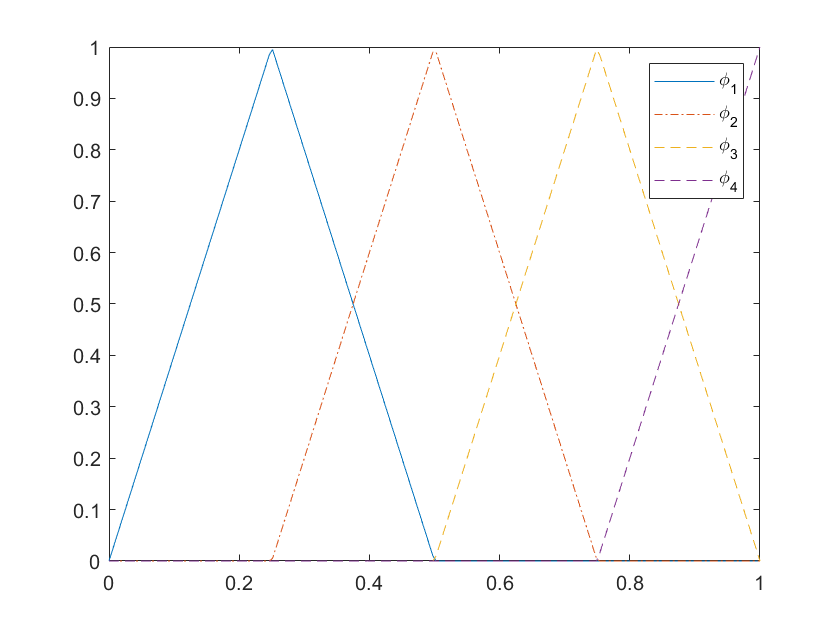

clear
Num_x_hat = 200;
hat_x = linspace(0,1,Num_x_hat);
OneFour = Num_x_hat/4;
TwoFour = Num_x_hat/2;
ThreeFour = 3*Num_x_hat/4;
%define the each stop point.
phi1 = [4*hat_x(1:OneFour) -4*hat_x(OneFour + 1:TwoFour) + 2 ...
    0*hat_x(TwoFour + 1:Num_x_hat)];
%phi1
phi2 = [0*hat_x(1:OneFour) 4*hat_x(OneFour + 1:TwoFour) - 1 ...
    -4*hat_x(TwoFour + 1:ThreeFour) + 3 0*hat_x(ThreeFour + 1:Num_x_hat)];
%phi2
phi3 = [0*hat_x(1:TwoFour) 4*hat_x(TwoFour + 1:ThreeFour) - 2 ...
    -4*hat_x(ThreeFour + 1:Num_x_hat) + 4];
%phi3
phi4 = [0*hat_x(1:ThreeFour) 4*hat_x(ThreeFour + 1:Num_x_hat)-3];
%phi4
plot(hat_x, phi1)
hold on
plot(hat_x, phi2,'-.')
plot(hat_x, phi3,'--')
plot(hat_x, phi4,'--')
legend('\phi_1','\phi_2','\phi_3','\phi_4')
hold off

Fig 1.1

The plot shows three hat function by phi1 phi2 and phi3 in the different line style. Which phi1 is in solid line '—', phi2 is in dot line '._.' and phi3 is in '--',phi4 is half hat function with purple.

The Stiffness Martix has the formular:

$\textrm{Ku}=b$                    (2)

which $K=$$\left\lbrack \begin{array}{cccc}
\left\langle {\phi_1 }^{\prime } ,{\phi_1 }^{\prime } \right\rangle  & \left\langle {\phi_2 }^{\prime } ,{\phi_1 }^{\prime } \right\rangle  & \left\langle {\phi_3 }^{\prime } ,{\phi_1 }^{\prime } \right\rangle  & \left\langle {\phi_4 }^{\prime } ,{\phi_1 }^{\prime } \right\rangle \\
\left\langle {\phi_1 }^{\prime } ,{\phi_2 }^{\prime } \right\rangle  & \left\langle {\phi_2 }^{\prime } ,{\phi_2 }^{\prime } \right\rangle  & \left\langle {\phi_3 }^{\prime } ,{\phi_2 }^{\prime } \right\rangle  & \left\langle {\phi_4 }^{\prime } ,{\phi_2 }^{\prime } \right\rangle \\
\left\langle {\phi_1 }^{\prime } ,{\phi_3 }^{\prime } \right\rangle  & \left\langle {\phi_2 }^{\prime } ,{\phi_3 }^{\prime } \right\rangle  & \left\langle {\phi_3 }^{\prime } ,{\phi_3 }^{\prime } \right\rangle  & \left\langle {\phi_4 }^{\prime } ,{\phi_3 }^{\prime } \right\rangle \\
\left\langle {\phi_1 }^{\prime } ,{\phi_4 }^{\prime } \right\rangle  & \left\langle {\phi_2 }^{\prime } ,{\phi_4 }^{\prime } \right\rangle  & \left\langle {\phi_3 }^{\prime } ,{\phi_4 }^{\prime } \right\rangle  & \left\langle {\phi_4 }^{\prime } ,{\phi_4 }^{\prime } \right\rangle 
\end{array}\right\rbrack ,u=\left\lbrack \begin{array}{c}
\alpha_1 \\
\alpha_2 \\
\alpha_3 \\
\alpha_4 
\end{array}\right\rbrack ,\;b=4\phi \left(1\right)-\left\lbrack \begin{array}{c}
\left\langle f\left(x\right),\phi_1 \right\rangle \\
\left\langle f\left(x\right),\phi_2 \right\rangle \\
\left\langle f\left(x\right),\phi_3 \right\rangle \\
\left\langle f\left(x\right),\phi_4 \right\rangle 
\end{array}\right\rbrack$

Find the derivative of$\phi_1$$\phi_2$$\phi_3$:

${\phi_1 }^{\prime } \left(x\right)=\left\lbrace \begin{array}{cc}
4 & 0\le x\le \frac{1}{4}\\
-4 & \frac{1}{4}\le x\le \frac{1}{2}\\
0 & \frac{1}{2}\le x\le 1
\end{array}\right.$${\phi_2 }^{\prime } \left(x\right)=\left\lbrace \begin{array}{cc}
0 & 0\le x\le \frac{1}{4}\\
4 & \frac{1}{4}\le x\le \frac{1}{2}\\
-4 & \frac{1}{2}\le x\le \frac{3}{4}\\
0 & \frac{3}{4}\le x\le 1
\end{array}\right.$${\phi_3 }^{\prime } \left(x\right)=\left\lbrace \begin{array}{cc}
0 & 0\le x\le \frac{1}{2}\\
4 & \frac{1}{2}\le x\le \frac{3}{4}\\
-4 & \frac{3}{4}\le x\le 1
\end{array}\right.$   ${\phi_4 }^{\prime } \left(x\right)=\left\lbrace \begin{array}{cc}
0 & 0\le x\le \frac{3}{4}\\
 & \\
4 & \frac{3}{4}\le x\le 1
\end{array}\right.$                 (3)

Then compute (2) with (3) :


$$\left\langle {\phi_1 }^{\prime } ,{\phi_1 }^{\prime } \right\rangle =\int_0^1 {\left({\phi_1 }^{\prime } \left(x\right)\right)}^2 \textrm{dx}=\int_0^{\frac{1}{4}} 4^2 \textrm{dx}+\int_{\frac{1}{4}}^{\frac{1}{2}} {\left(-4\right)}^2 \textrm{dx}+\int_{\frac{1}{2}}^1 0\textrm{dx}=8$$



$$\left\langle {\phi_2 }^{\prime } ,{\phi_2 }^{\prime } \right\rangle =\int_0^1 {\left({\phi_2 }^{\prime } \left(x\right)\right)}^2 \textrm{dx}=\int_0^{\frac{1}{4}} 0\textrm{dx}+\int_{\frac{1}{4}}^{\frac{1}{2}} 4^2 \textrm{dx}+\int_{\frac{1}{2}}^{\frac{3}{4}} {\left(-4\right)}^2 \textrm{dx}+\int_{\frac{3}{4}}^1 0\textrm{dx}=8$$



$$\left\langle {\phi_3 }^{\prime } ,{\phi_3 }^{\prime } \right\rangle =\int_0^1 {\left({\phi_3 }^{\prime } \left(x\right)\right)}^2 \mathrm{dx}=\int_0^{\frac{1}{2}} 0\mathrm{dx}+\int_{\frac{1}{2}}^{\frac{3}{4}} {\left(4\right)}^2 \mathrm{dx}+\int_{\frac{3}{4}}^1 {\left(-4\right)}^2 \mathrm{dx}=8$$



$$\left\langle {\phi_4 }^{\prime } ,{\phi_4 }^{\prime } \right\rangle =\int_0^1 {\left({\phi_4 }^{\prime } \left(x\right)\right)}^2 \textrm{dx}=\int_0^{\frac{3}{4}} 0\textrm{dx}+\int_{\frac{3}{4}}^1 {\left(4\right)}^2 \textrm{dx}=4$$



$$\left\langle {\phi_1 }^{\prime } ,{\phi_2 }^{\prime } \right\rangle =\left\langle {\phi_2 }^{\prime } ,{\phi_1 }^{\prime } \right\rangle =\int_0^1 {\phi_1 }^{\prime } \left(x\right){\phi_2 }^{\prime } \left(x\right)\textrm{dx}=\int_0^{\frac{1}{4}} 0\textrm{dx}+\int_{\frac{1}{4}}^{\frac{1}{2}} -16\textrm{dx}+\int_{\frac{1}{2}}^{\frac{3}{4}} 0\textrm{dx}+\int_{\frac{3}{4}}^1 0\textrm{dx}=-4$$



$$\left\langle {\phi_1 }^{\prime } ,{\phi_3 }^{\prime } \right\rangle =\left\langle {\phi_3 }^{\prime } ,{\phi_1 }^{\prime } \right\rangle =\int_0^1 {\phi_1 }^{\prime } \left(x\right){\phi_3 }^{\prime } \left(x\right)\textrm{dx}=\int_0^{\frac{1}{4}} 0\textrm{dx}+\int_{\frac{1}{4}}^{\frac{1}{2}} 0\textrm{dx}+\int_{\frac{1}{2}}^{\frac{3}{4}} 0\textrm{dx}+\int_{\frac{3}{4}}^1 0\textrm{dx}=0$$



$$\left\langle {\phi_1 }^{\prime } ,{\phi_4 }^{\prime } \right\rangle =\left\langle {\phi_4 }^{\prime } ,{\phi_1 }^{\prime } \right\rangle =\int_0^1 {\phi_1 }^{\prime } \left(x\right){\phi_4 }^{\prime } \left(x\right)\textrm{dx}=\int_0^{\frac{1}{4}} 0\textrm{dx}+\int_{\frac{1}{4}}^{\frac{1}{2}} 0\textrm{dx}+\int_{\frac{1}{2}}^{\frac{3}{4}} 0\textrm{dx}+\int_{\frac{3}{4}}^1 0\textrm{dx}=0$$



$$\left\langle {\phi_2 }^{\prime } ,{\phi_3 }^{\prime } \right\rangle =\left\langle {\phi_3 }^{\prime } ,{\phi_2 }^{\prime } \right\rangle =\int_0^1 {\phi_2 }^{\prime } \left(x\right){\phi_3 }^{\prime } \left(x\right)\textrm{dx}=\int_0^{\frac{1}{4}} 0\textrm{dx}+\int_{\frac{1}{4}}^{\frac{1}{2}} 0\textrm{dx}+\int_{\frac{1}{2}}^{\frac{3}{4}} -16\textrm{dx}+\int_{\frac{3}{4}}^1 0\textrm{dx}=-4$$



$$\left\langle {\phi_2 }^{\prime } ,{\phi_4 }^{\prime } \right\rangle =\left\langle {\phi_4 }^{\prime } ,{\phi_2 }^{\prime } \right\rangle =\int_0^1 {\phi_2 }^{\prime } \left(x\right){\phi_4 }^{\prime } \left(x\right)\textrm{dx}=\int_0^{\frac{1}{4}} 0\textrm{dx}+\int_{\frac{1}{4}}^{\frac{1}{2}} 0\textrm{dx}+\int_{\frac{1}{2}}^{\frac{3}{4}} 0\textrm{dx}+\int_{\frac{3}{4}}^1 0\textrm{dx}=0$$



$$\left\langle {\phi_3 }^{\prime } ,{\phi_4 }^{\prime } \right\rangle =\left\langle {\phi_4 }^{\prime } ,{\phi_3 }^{\prime } \right\rangle =\int_0^1 {\phi_3 }^{\prime } \left(x\right){\phi_4 }^{\prime } \left(x\right)\textrm{dx}=\int_0^{\frac{1}{4}} 0\textrm{dx}+\int_{\frac{1}{4}}^{\frac{1}{2}} 0\textrm{dx}+\int_{\frac{1}{2}}^{\frac{3}{4}} 0\textrm{dx}+\int_{\frac{3}{4}}^1 -16\textrm{dx}=-4$$


So $K=\left\lbrack \begin{array}{cccc}
8 & -4 & 0 & 0\\
-4 & 8 & -4 & 0\\
0 & -4 & 8 & -4\\
0 & 0 & -4 & 4
\end{array}\right\rbrack$                    (4)

Then compute b with (1):


$$\left\langle f\left(x\right),\phi_1 \right\rangle =\int_0^1 f\left(x\right)\phi_1 \left(x\right)=\int_0^{\frac{1}{4}} \left(x-2\right)4x\textrm{dx}+\int_{\frac{1}{4}}^{\frac{2}{4}} \left(x-2\right)\left(-4x+2\right)\textrm{dx}+\int_{\frac{1}{2}}^1 0\textrm{dx}=-\frac{7}{16}$$



$$\left\langle f\left(x\right),\phi_2 \right\rangle =\int_0^1 f\left(x\right)\phi_2 \left(x\right)=\int_0^{\frac{1}{4}} 0\textrm{dx}+\int_{\frac{1}{4}}^{\frac{2}{4}} \left(x-2\right)\left(4x-1\right)\textrm{dx}+\int_{\frac{1}{2}}^{\frac{3}{4}} \left(x-2\right)\left(-4x+3\right)\textrm{dx}+\int_{\frac{3}{4}}^1 0\textrm{dx}=-\frac{3}{8}$$



$$\left\langle f\left(x\right),\phi_3 \right\rangle =\int_0^1 f\left(x\right)\phi_3 \left(x\right)=\int_0^{\frac{1}{2}} 0\textrm{dx}+\int_{\frac{1}{2}}^{\frac{3}{4}} \left(x-2\right)\left(4x-2\right)\textrm{dx}+\int_{\frac{3}{4}}^1 \left(x-2\right)\left(-4x+4\right)\textrm{dx}=-\frac{5}{16}$$



$$\left\langle f\left(x\right),\phi_4 \right\rangle =\int_0^1 f\left(x\right)\phi_4 \left(x\right)=\int_0^{\frac{1}{2}} 0\textrm{dx}+\int_{\frac{1}{2}}^{\frac{3}{4}} 0\textrm{dx}+\int_{\frac{3}{4}}^1 \left(x-2\right)\left(4x-3\right)\textrm{dx}=-\frac{13}{96}$$


so $b=4\left\lbrack \begin{array}{c}
0\\
0\\
0\\
1
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
-\frac{7}{16}\\
-\frac{3}{8}\\
-\frac{5}{16}\\
-\frac{13}{96}
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\frac{7}{16}\\
\frac{3}{8}\\
\frac{5}{16}\\
\frac{397}{96}
\end{array}\right\rbrack$            (5)

So we could compute u from $\mathrm{Ku}=b$

$\left\lbrack \begin{array}{cccc}
8 & -4 & 0 & 0\\
-4 & 8 & -4 & 0\\
0 & -4 & 8 & -4\\
0 & 0 & -4 & 4
\end{array}\right\rbrack$$\left\lbrack \begin{array}{c}
\alpha_1 \\
\alpha_2 \\
\alpha_3 \\
\alpha_4 
\end{array}\right\rbrack$=$\left\lbrack \begin{array}{c}
\frac{7}{16}\\
\frac{3}{8}\\
\frac{5}{16}\\
\frac{397}{96}
\end{array}\right\rbrack$

c)ii

(ii) Then, write code in Matlab to solve your problem from (i) to determine the solution u(x). Compare your result to that from (a) at the grid nodes.

h = 1/4;%define h
n = 1/h - 1;%compute n
x = linspace(0, 1, 100);%define x
xg = linspace(0,1,n + 2);%true x with 5 points
up = realf(xg);%true value of the grid
u = realf(x);%true solution
b = [7/16; 3/8; 5/16; 397/96];%equation (5)
k = [8 -4 0 0;
    -4 8 -4 0;
     0 -4 8 -4;
     0 0 -4 4;];%equaiton (4)
coe = k\b;%solve equation (2)
coe = [0;coe]

coe =          0
    1.3151
    2.5208
    3.6328
    4.6667


The solution with h=0.25 is above.

error=abs(coe(:) - up(:))%compute the error

error = 	1.0e+-14 *

         0
    0.0888
    0.2220
    0.2220
    0.1776


Also we could see the error of the result of grid we compute are small enough.

So if we graph the solution and true value on the same page.

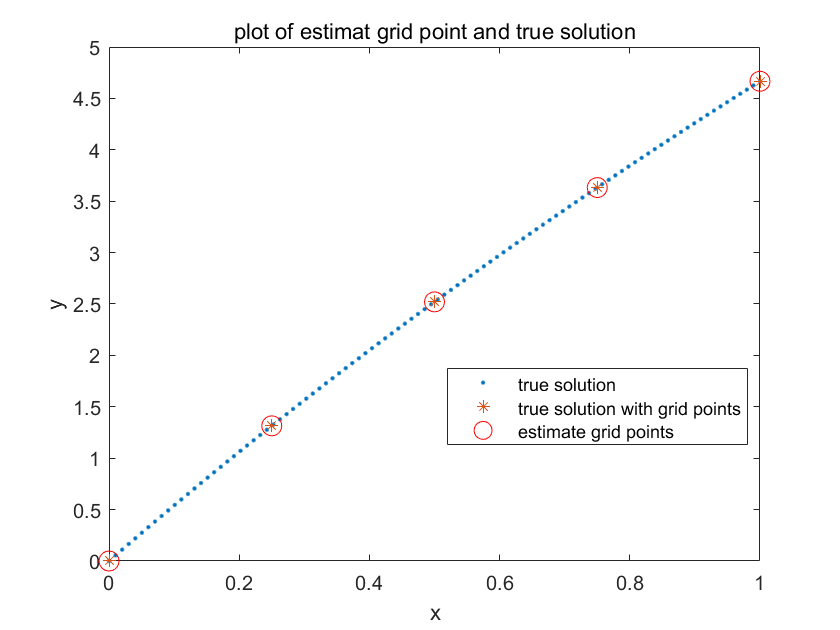

%plot
plot(x, u, '.')
hold on
plot(xg, up, '*')
plot(xg, coe, 'o', 'Markersize', 10, 'Color','r')
legend('true solution', 'true solution with grid points', 'estimate grid points','Location','best')
xlabel('x')
ylabel('y')
title('plot of estimat grid point and true solution')
hold off

function [r]=realf(x)
%Function of compute the true value for comparison. from (a)
    r = 1/6*x.^3 - x.^2+11/2*x;
end

Fig 1.2 This plot shows the result we compute by FEM compare with true solution. On the graph they on the same spot.